#### neighborhood of Singular Configuration 1

clc
clear all;
close all;
M = [[1, 0, 0, 0.088];[0, -1, 0, 0];[0, 0, -1, 0.926];[0, 0, 0, 1]];
S = [[0;0;1;0;0;0],[0;1;0;-0.333;0;0],[0;0;1;0;0;0],[0;-1;0;0.316+0.333;0;-0.0825],[0;0;1;0;0;0],[0;-1;0;0.384+0.316+0.333;0;0],[0;0;-1;0;0.088;0]];
Theta = [0; 0.01; 0.51*pi; 0; -0.51*pi; 0; 0];
T1 = FK_SpaceForm(S, M, Theta);
Js = J_SpaceForm(S, Theta);
robot = importrobot('Franka_Emika_Panda.urdf');

robot.DataFormat = 'column';
figure
show(robot,Theta,'Visuals','on','Frames','off')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


x = T1(1,4);
y = T1(2,4);
z = T1(3,4);
P = [x,y,z];

p_ss = VecToso3(P);
J_g_1 = [eye(3) zeros(3);
        -p_ss eye(3)] * Js;

J_g_w = J_g_1(1:3,:);
J_plus_w = transpose(J_g_w)*inv(J_g_w*transpose(J_g_w));
J_w = transpose(J_plus_w)*J_plus_w;

A_w = inv(J_w);
[v_w,lambda_w] = eig(A_w)

v_w =    -0.9995    0.0313    0.0067
    0.0313    0.9995   -0.0001
    0.0067   -0.0002    1.0000


lambda_w =     0.9981         0         0
         0    2.0020         0
         0         0    3.9999


Volume_angular_vel_ellipsoid = sqrt(lambda_w(1,1)*lambda_w(2,2)*lambda_w(3,3))

Volume_angular_vel_ellipsoid = 2.8271

hold on
syms X 
syms Y
syms Z
angular_velocity_ellipsoid=@(X,Y,Z) [X-x Y-y Z-z]*J_w*[X-x;Y-y;Z-z]-0.03;
fimplicit3(angular_velocity_ellipsoid)

hold on
arrow3([x y z],[x y z]+v_w(:,1)' ,'m')
hold on
arrow3([x y z],[x y z]+v_w(:,2)' ,'m')
hold on
arrow3([x y z],[x y z]+v_w(:,3)' ,'m')
title('Angular-velocity Manipulability Ellipsoid for the neighborhood of Singular Configuration 1 ',  'Interpreter','latex', 'FontSize',24);


J_g_v = J_g_1(4:6,:);
J_plus_v = transpose(J_g_v)*inv(J_g_v*transpose(J_g_v));
J_v = transpose(J_plus_v)*J_plus_v;
A_v = inv(J_v);
[v_v,lambda_v] = eig(A_v)

v_v =     0.1267    0.0532   -0.9905
   -0.2499    0.9681    0.0200
    0.9599    0.2450    0.1360


lambda_v =     0.0113         0         0
         0    0.1068         0
         0         0    0.3688


Volume_linear_vel_ellipsoid = sqrt(lambda_v(1,1)*lambda_v(2,2)*lambda_v(3,3))

Volume_linear_vel_ellipsoid = 0.0211

figure
show(robot,Theta,'Visuals','on','Frames','off')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
velocity_ellipsoid=@(X,Y,Z) [X-x Y-y Z-z]*J_v*[X-x;Y-y;Z-z] -0.5;
fimplicit3(velocity_ellipsoid)

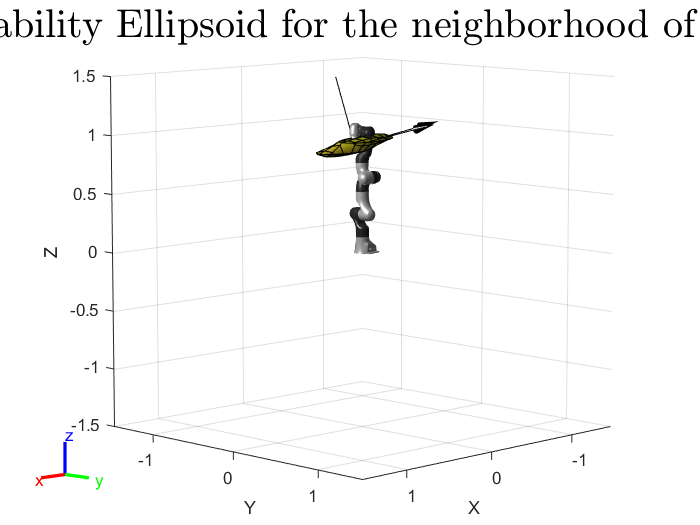

hold on
arrow3([x y z],[x y z]+v_v(:,1)' ,'k')
hold on
arrow3([x y z],[x y z]+v_v(:,2)' ,'k')
hold on
arrow3([x y z],[x y z]+v_v(:,3)' ,'k')
title('Linear-velocity Manipulability Ellipsoid for the neighborhood of Singular Configuration 1 ', 'Interpreter','latex', 'FontSize',24);

figure
show(robot,Theta,'Visuals','on','Frames','off')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
fimplicit3(velocity_ellipsoid)

hold on
fimplicit3(angular_velocity_ellipsoid)

title('Linear and Angular-velocity Manipulability Ellipsoid for the neighborhood of Singular Configuration 1 ', 'Interpreter','latex', 'FontSize',24 );